# Train PPO Agent to Land Rocket

This example shows how to train a proximal policy optimization (PPO) agent with a discrete action space to land a rocket on the ground. For more information on PPO agents, see [Proximal Policy Optimization Agents](docid:rl_ug#mw_84b69098-f745-40ba-8aad-c5d46458237f).

## Environment

The environment in this example is a 3-DOF rocket represented by a circular disc with mass. The rocket has two thrusters for forward and rotational motion. Gravity acts vertically downwards, and there are no aerodynamic drag forces. The training goal is to make the robot land on the ground at a specified location.

For this environment:

- Motion of the rocket is bounded in X (horizontal axis) from -100 to 100 meters and Y (vertical axis) from 0 to 120 meters.

- The goal position is at (0,0) meters and the goal orientation is 0 radians.

- The sample time is 0.1 seconds.

- The observations from the environment are the rocket position $\left(x,y\right)$, orientation $\left(\theta \right)$, velocity $\left(\dot{x} ,\dot{y} \right)$, angular velocity $\left(\theta^˙ \right)$, and a sensor reading that detects rough landing (-1), soft landing (1) or airborne (0) condition. The observations are normalized between -1 and 1.

- At the beginning of every episode, the rocket starts from a random initial $x$ position and orientation. The altitude is always reset to 100 meters.

- The reward $r_t$ provided at the time step $t$ is as follows.


$$\begin{array}{l}
\\
\textrm{reward}=1-\ldotp 1*\left(\left(\textrm{abs}\left(\textrm{current}\_\textrm{position}-\textrm{target}\_\textrm{position}\right)\right)\ldotp \textrm{sum}\left(\right)\right)**2
\end{array}$$


Here:

- $x_t$,$y_t$,${\dot{x} }_t$, and ${\dot{y} }_t$ are the positions and velocities of the rocket along the x and y axes.

- ${\hat{d} }_t$ is the normalized distance of the rocket from the goal position.

- ${\hat{v} }_t$ is the normalized speed of the rocket.

- $d_{\max }$ and $v_{\max }$ are the maximum distances and speeds within the state-space.

- $\theta_t$ is the orientation with respect to the vertical axis.

- $L_t$ and $R_t$ are the action values for the left and right thrusters.

- $r_1$ is a reward for minimizing distance and speed simultaneously.

- $r_2$ is a reward for minimizing the orientation of the rocket.

- $r_3$ is a reward for minimizing control effort.

- $r_4$ is a sparse reward for soft-landing with horizontal and vertical velocities less than 0.5 m/s.

## Create MATLAB Environment

Create a MATLAB environment for the rocket lander using the `RocketLander` class.

env = Rocket_Lander;

Obtain the observation and action information from the environment.

actionInfo = getActionInfo(env);
observationInfo = getObservationInfo(env);
numObs = observationInfo.Dimension(1);
numAct = numel(actionInfo.Elements);

Fix the random generator seed for reproducibility.

rng(0)

## Create PPO Agent

The PPO agent in this example operates on a discrete action space. At every time step, the agent selects one of the following discrete action pairs.


$$\begin{array}{l}
L,\;L-\textrm{do}\;\textrm{nothing}\\
L,\;M-\textrm{fire}\;\textrm{right}\;\left(\textrm{med}\right)\\
L,\;H-\textrm{fire}\;\textrm{right}\;\left(\textrm{high}\right)\\
M,\;L-\textrm{fire}\;\textrm{left}\;\left(\textrm{med}\right)\\
M,\;M-\textrm{fire}\;\textrm{left}\;\left(\textrm{med}\right)+\textrm{right}\;\left(\textrm{med}\right)\\
M,\;H-\textrm{fire}\;\textrm{left}\;\left(\textrm{med}\right)+\textrm{right}\;\left(\textrm{high}\right)\\
H,\;L-\textrm{fire}\;\textrm{left}\;\left(\textrm{high}\right)\\
H,\;M-\textrm{fire}\;\textrm{left}\;\left(\textrm{high}\right)+\textrm{right}\;\left(\textrm{med}\right)\\
H,\;H-\textrm{fire}\;\textrm{left}\;\left(\textrm{high}\right)+\textrm{right}\;\left(\textrm{high}\right)
\end{array}$$


Here, $L=0\ldotp 0,M=0\ldotp 5$ and $H=1\ldotp 0$ are normalized thrust values for each thruster.

To estimate the policy and value function, the agent maintains function approximators for the actor and critic, which are modeled using deep neural networks. The training can be sensitive to the initial network weights and biases, and results can vary with different sets of values. In this example, the network weights are randomly initialized to small values. To load a set of predefined values instead, set `predefinedWeightsandBiases` to `true`.

criticLayerSizes = [200 100];
actorLayerSizes = [200 100];

predefinedWeightsandBiases = false;
if predefinedWeightsandBiases
    load('PredefinedWeightsAndBiases.mat');
else
    createNetworkWeights;
end

Create the critic deep neural network with six inputs and one output. The output of the critic network is the discounted long term reward for the input observations.

criticNetwork = [imageInputLayer([numObs 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(criticLayerSizes(1),'Name','CriticFC1', ... 
                                            'Weights',weights.criticFC1, ...
                                            'Bias',bias.criticFC1)
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(criticLayerSizes(2),'Name','CriticFC2', ...
                                            'Weights',weights.criticFC2, ... 
                                            'Bias',bias.criticFC2)
    reluLayer('Name','CriticRelu2')
    fullyConnectedLayer(1,'Name','CriticOutput',...
                          'Weights',weights.criticOut,...
                          'Bias',bias.criticOut)];

Create the critic representation.

criticOpts = rlRepresentationOptions('LearnRate',1e-3);
critic = rlValueRepresentation(criticNetwork,env.getObservationInfo, ...
                          'Observation',{'observation'},criticOpts);

Create the actor using a deep neural network with six inputs and two outputs. The outputs of the actor network are the probabilities of taking each possible action pair. Each action pair contains normalized action values for each thruster. The environment `step` function scales these values to determine the actual thrust values.

actorNetwork = [imageInputLayer([numObs 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(actorLayerSizes(1),'Name','ActorFC1',...
                                           'Weights',weights.actorFC1,...
                                           'Bias',bias.actorFC1)
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(actorLayerSizes(2),'Name','ActorFC2',...
                                           'Weights',weights.actorFC2,...
                                           'Bias',bias.actorFC2)
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(numAct,'Name','Action',...
                               'Weights',weights.actorOut,...
                               'Bias',bias.actorOut)
    softmaxLayer('Name','actionProbability')
    ];  

Create the actor using a stochastic actor representation. 

actorOptions = rlRepresentationOptions('LearnRate',1e-3);
actor = rlStochasticActorRepresentation(actorNetwork,env.getObservationInfo,env.getActionInfo,... 
                         'Observation',{'observation'}, actorOptions);

The PPO agent generates experiences for `ExperienceHorizon` number of steps or until the end of the episode. Then it trains on those experiences using mini-batches for a specified number of epochs. 

- Set the `ExperienceHorizon` to 512 steps, which is slightly less than half the total simulation duration of 1200 steps.

- Use the `"gae"` method, which computes the advantage function based on the smoothed discounted sum of temporal differences.

- To improve training stability, use an objective function clip factor of 0.2. 

- Discount factors that are close to 1 encourage long term rewards. Use a discount factor of 0.9995, which has a half-life of log(0.5)/log(0.9995) ≈ 1386 steps.

Specify the agent options using `rlPPOAgentOptions`.

opt = rlPPOAgentOptions('ExperienceHorizon',512,...
                        'ClipFactor',0.2,...
                        'EntropyLossWeight',0.02,...
                        'MiniBatchSize',64,...
                        'NumEpoch',3,...
                        'AdvantageEstimateMethod','gae',...
                        'GAEFactor',0.95,...
                        'SampleTime',env.Ts,...
                        'DiscountFactor',0.9995);

Create the PPO agent.

agent = rlPPOAgent(actor,critic,opt);

## Train Agent

To train the PPO agent, specify the following training options.

- Run the training for at most 20000 episodes, with each episode lasting at most 1200 time steps.

- Stop the training when the average reward over 100 consecutive episodes is 10000. This value indicates that the agent is consistently receiving the reward for soft landing.

- Save a copy of the agent for each episode where the episode reward is 11000 or more.

trainOpts = rlTrainingOptions(...
    'MaxEpisodes',20000,...
    'MaxStepsPerEpisode',1200,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',10000,...
    'ScoreAveragingWindowLength',100,...
    'SaveAgentCriteria',"EpisodeReward",...
    'SaveAgentValue',11000);

Plot the rocket lander environment to visualize the training or simulation.

plot(env)

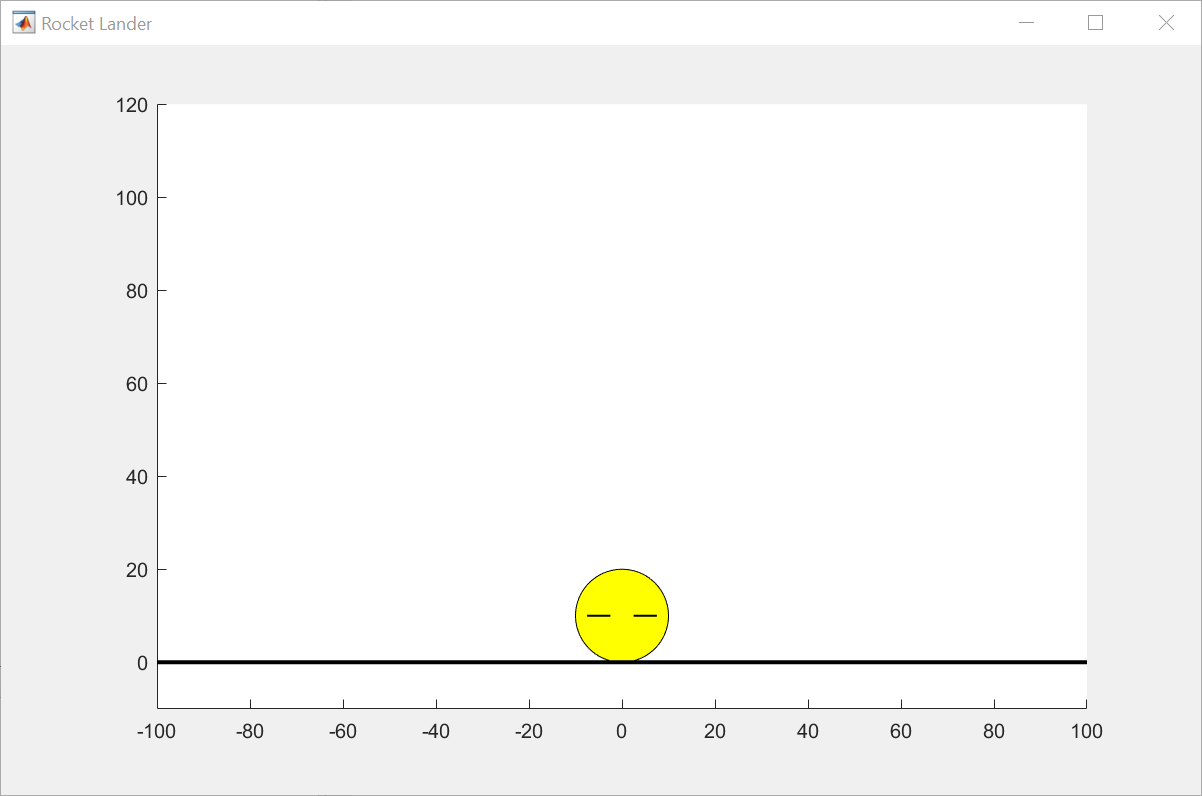

Train the agent using the `train` function. Due to the complexity of the environment, this process is computationally intensive and takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`.

doTraining = false;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained parameters for the example.
    load('RocketLanderPPOAgentParams.mat');
    loadPretrainedParams(agent,actorParams,criticParams)
end

ans =   rlPPOAgent with properties:

    AgentOptions: [1×1 rl.option.rlPPOAgentOptions]


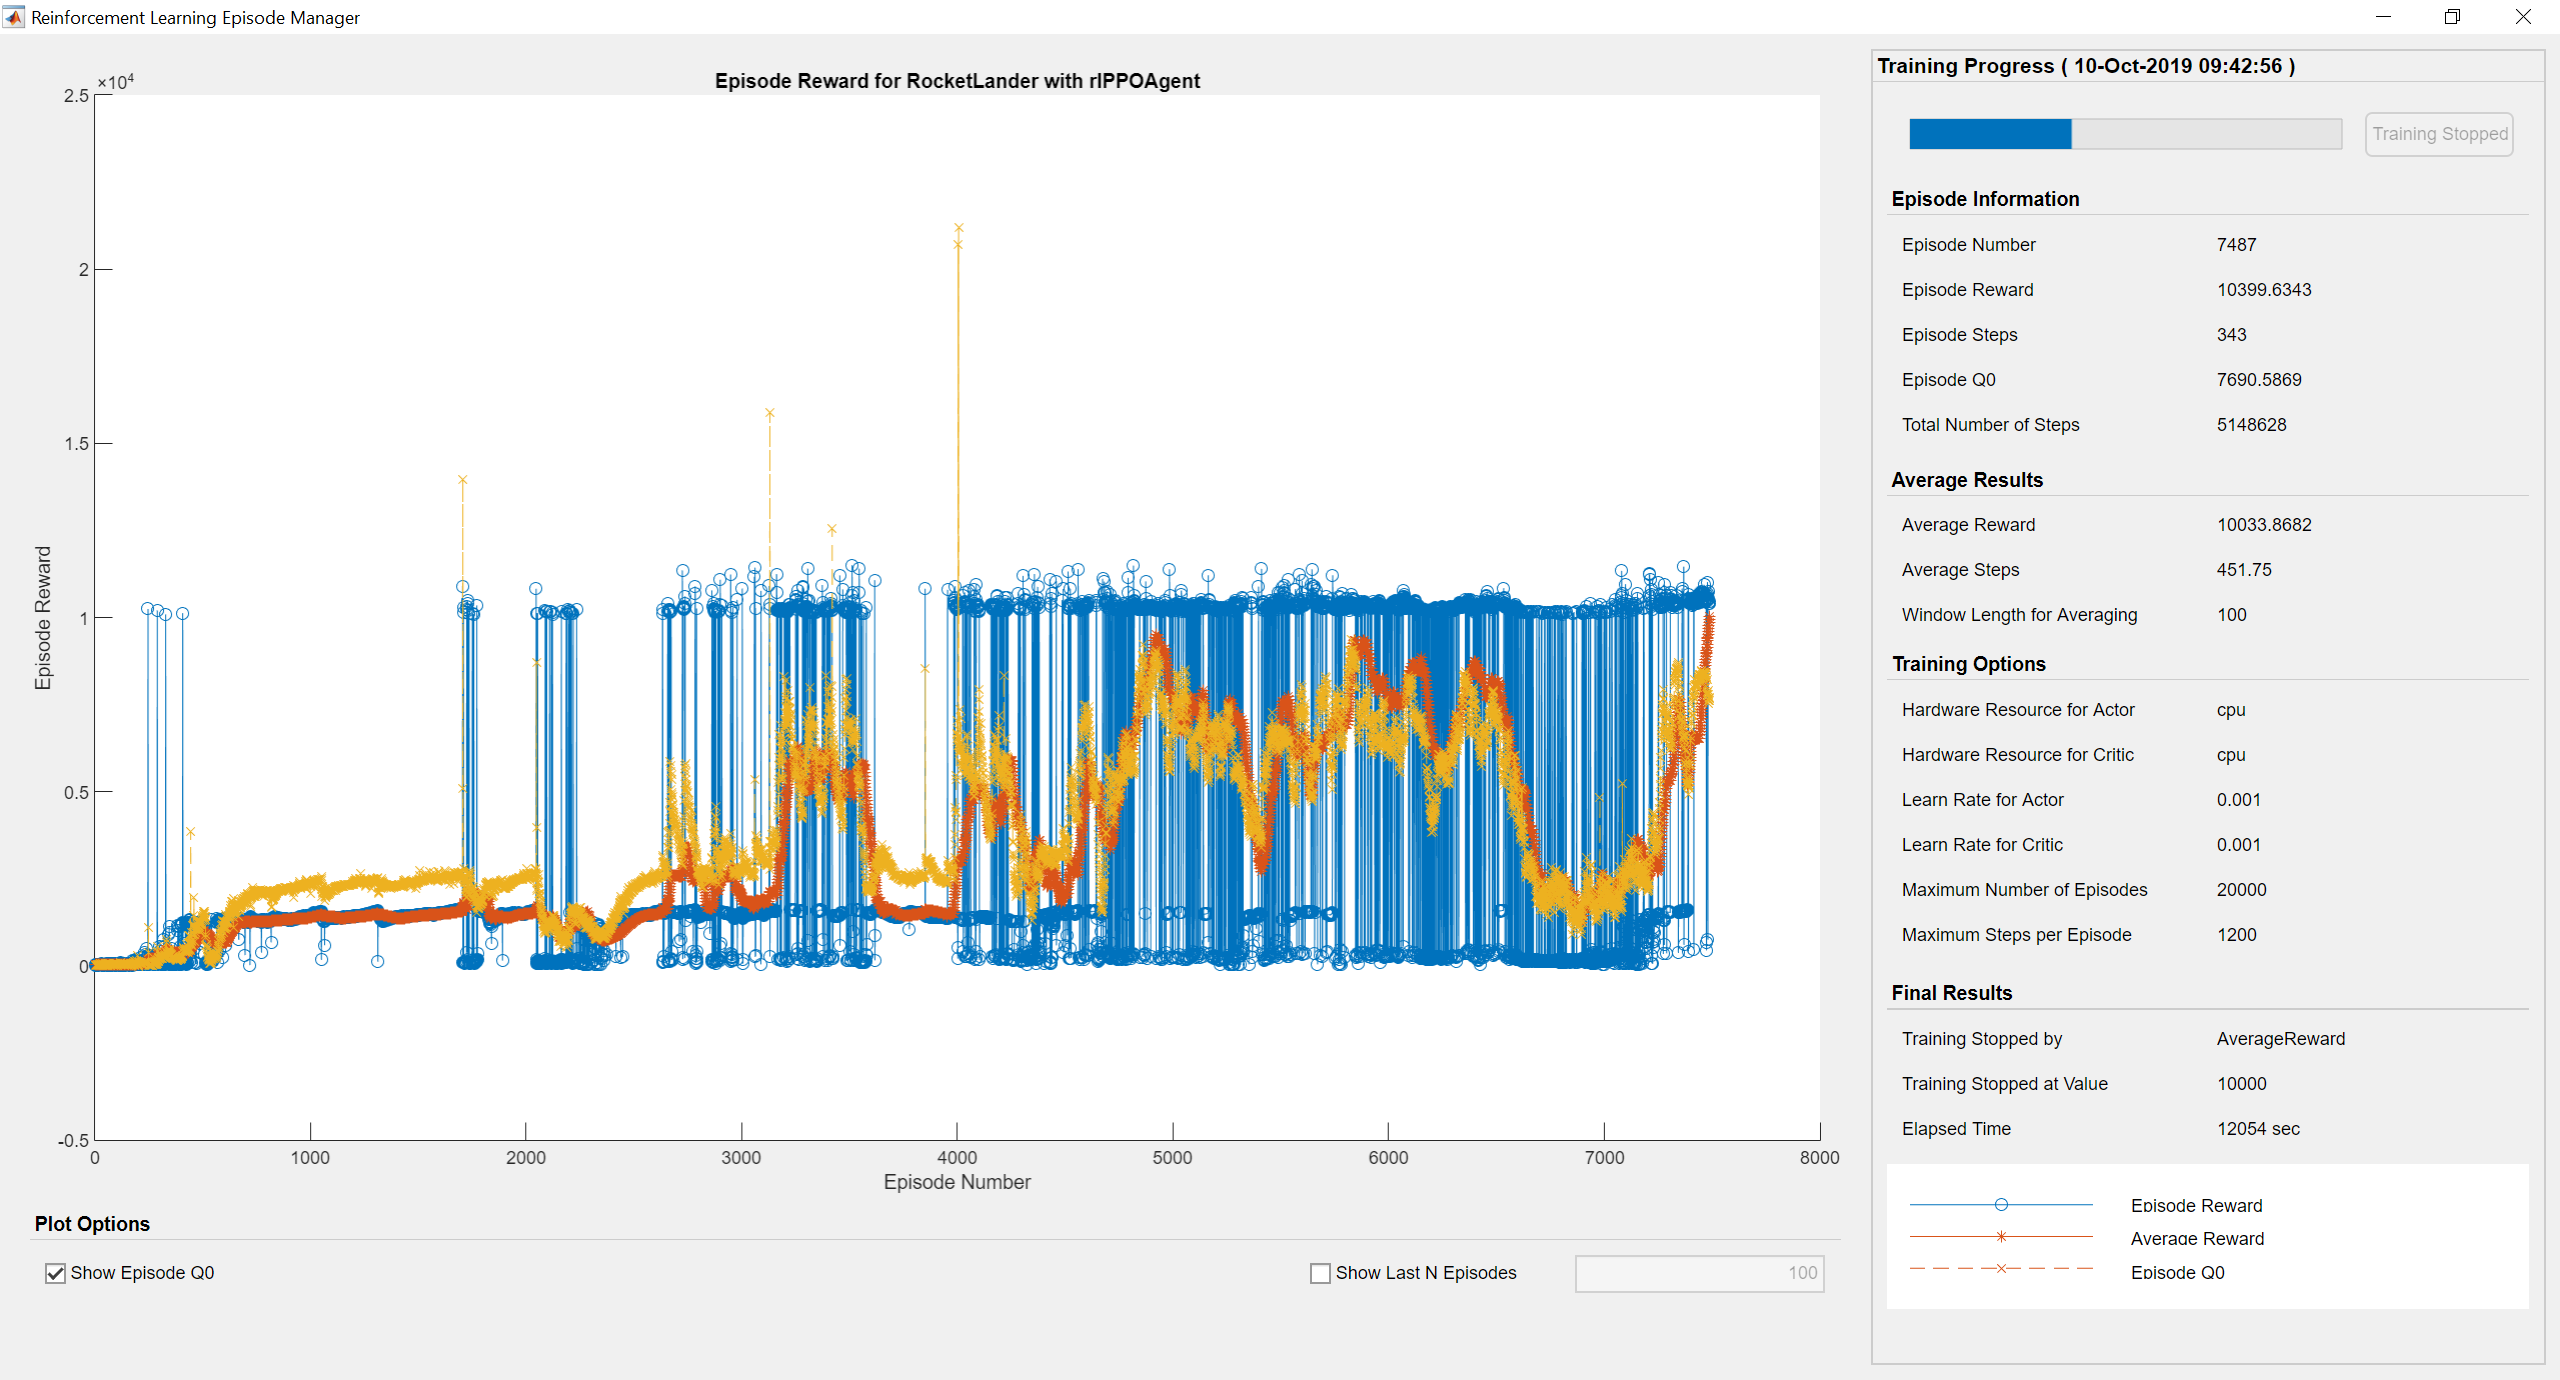

## Simulate

Simulate the trained agent within the environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

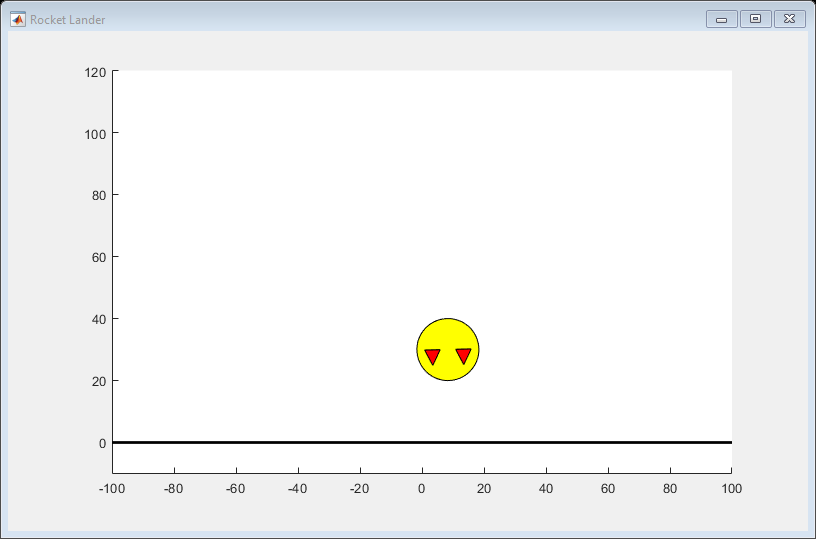

Tf = 120;  % Total simulation length (seconds)
simOptions = rlSimulationOptions('MaxSteps',ceil(Tf/env.Ts));
experience = sim(env,agent,simOptions);

## Local Function

Function to update agent with pretrained parameters

function agent = loadPretrainedParams(agent,actorParams,criticParams)
% Set actor parameters.
actor  = getActor(agent);
pretrainedActor  = setLearnableParameters(actor,actorParams);
% Set critic parameters.
critic = getCritic(agent);
pretrainedCritic = setLearnableParameters(critic,criticParams);
% Set actor and critic in agent.
agent = setActor(agent,pretrainedActor);
agent = setCritic(agent,pretrainedCritic);
end

*Copyright 2019 The MathWorks, Inc.*